# Continuation

**Path continuation, determined by the residual-function fun(var,l)**

## Syntax

-   continuation(fun,var0,l_start,l_end,ds0)

-   continuation(___,Name,Value)

-   [var_all,l_all,exitflag,bif] = continuation(___)

## Description

TODO

## Examples

TODO

clear all;
close all;
clc;
addpath('..\src');
addpath('test_cases');

%% choose testfunction


% testfun01; % 0=!v.^2+5-exp((1/l)*v)
% testfun02; % Duffing: mu \ddot q + zeta \dot q + kappa q + \gamma q^3 = P cos( Om * t )
% testfun03; % Stochastic Duffing
% testfun04; % Point of intersection of circle and sin(radius)-scaled exponential function with radius as parameter
% testfun05; % function with bifurcation
% testfun06; % tests ellipsoid2
% testfun07; % Multidimensional (nd = 500)
% testfun08; % Pitchfork-Bifurkation
% testfun09; % circle

%% Solve:

## Name-Value Pair Arguments

Specify optional comma-separated pairs of Name,Value arguments. Name is the argument name and Value is the corresponding value. Name must appear inside quotes. You can specify several name and value pair arguments in any order as Name1,Value1,...,NameN,ValueN. Example: 'homotopy','off','solver','fsolve'

Name-Value Pairs listed alphabetically:

### TODO for Alwin:

- alpha_reverse

- include_reverse

### **???**

#### 'alpha_reverse' **— ???**

pi/2 (default) | scalar, double > 0

_____________________________________________________________________________________________________________________________________________________________________

### **arclength and stepsize control**

#### **'arclength' — determine arc-length-method**

'sphere' (default) | 'linear' | 'ellipsoid' | 'ellipsoid2' | 'unique'

TODO: What does this mean?

#### **'step_size_alpha_max' — **

#### **'step_size_angle' — **

#### **'step_size_control' — **

#### **'step_size_e_max' — **

#### **'ds_max' — set maximum radius**

inf (default) | scalar, double > 0

Defines maximum arclength to use, if set to inf arclength can rise unlimitedly.

TODO: ...

#### **'ds_min' — set maximum radius**

0 (default) | scalar, double >= 0 and < ds_max

Defines minimal arclength to use, if set to 0 arclength can get unlimitedly small.

_____________________________________________________________________________________________________________________________________________________________________

### **bifurcation**

#### **'bifurcation' — bifurcation analysis**

'off' (default) | 'on' = 'mark' | 'determine' | 'trace'

TODO: What is bifurcation?

#### **'stop_on_bifurcation' — **

#### **'n_bif_search' — **

_____________________________________________________________________________________________________________________________________________________________________

### **closed curve detection**

#### **'closed_counter' — counter for **closed_curve_detection

3 (default) | scalar, integer > 0

This counter is used for the detection of a closed curve. It specifiies how many times the current point must show up in the list of already found points. 

#### **'closed_curve_detection' — Determine a closed curve**

'off' (default) | 'on'

If activated it is investigated in continuation whether the explored curve is a closed one. If this is true, continuation breaks after closed_counter found points. A simple closed curve i.e. is a circle. 

% choose closed_counter
closed_counter = 2

closed_counter = 2

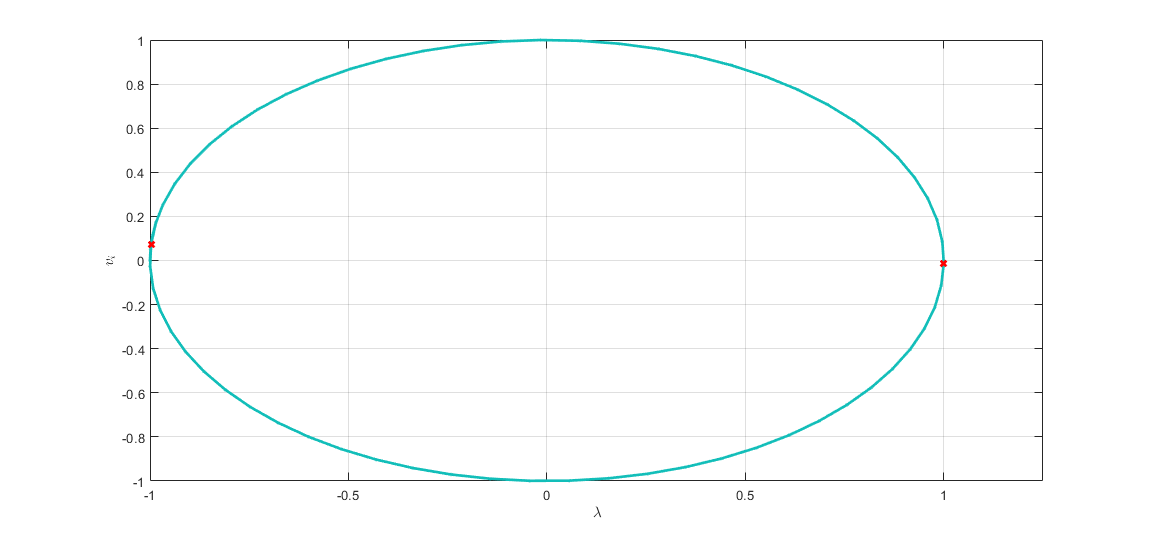

 
testfun09;
[vs,ls,exitflag,bifs] = continuation(fun,v0,lams,lame,ds0,'bifurcation','mark','ds_max',ds_max,'display','off','plot','on', 'closed_curve_detection', 'on', 'closed_counter', closed_counter);

**_____________________________________________________________________________________________________________________________________________________________________**

### **deflation**

#### **'deflation' — set deflation on/off**

'on' (default) | 'off'

TODO: What is deflation?

#### **'deflation_error_counter' — counter for **deflation

5 (default) | scalar, integer > 0

This counter is used to prevent deflation as long as the error_counter is smaller. Thereby it is guaranteed to not directly start deflation on the first invalid result.

**_____________________________________________________________________________________________________________________________________________________________________**

### **numeric jacobian**

#### **'diffquot' — Difference quotient for calculation of numeric jacobian**

'forward' (default) | 'central'

Used to calculate the numeric jacobian in case there's no jacobian passed to continuation.

**_____________________________________________________________________________________________________________________________________________________________________**

### **initial direction**

#### **'direction' — set initial direction**

sign(l_end-l_start)*[zeros(size(var0));1] (default) | +/- 1 | scalar, pmone | array, double, norm = 1, size: [length(var0)+1,1]'

TODO: ...

**_____________________________________________________________________________________________________________________________________________________________________**

#### **'display' — display progress**

'on' (default) | 'off'

TODO: What is displayed?

This option controls the output in the console. If activated, at first the initial solution is shown:

If **no initial solution** is found, it's shown in the consol. The output looks like this whenever a **next solution is found**:

The following is shown:

- at which λ the next solution is found 

- the next arc-length to use, based on arclength method

- the loop counter: increased in every run of the loop (even if no valid solution was found)

- the step counter: only increased if a valid solution is found in a loop run

- how many iterations were need to find a solution / optimal iteration steps 

If **no valid solution** is found, it's shown in the output. If homotopy is used, the console shows the start of the use and whether it worked or not.

Finally the elapsed time is shown in seconds. Moreover, **errors** and **warnings** plus detailed explainations are shown if problems occur.

**_____________________________________________________________________________________________________________________________________________________________________**

### **scaling**

#### **'dscale0' — starting value for scaling**

ones(length(var0)+1,1) (default) | array, double of size [length(var0)+1,1]' with all elements > 0

#### **'dscale_min' — minimal value for scaling**

1e-5 (default) | scalar, double > 0 | array, double of size [length(var0)+1,1]' with all elements > 0

#### **'scaling' — type of scaling**

'dynamicdscale' (default) | 'staticdscale' | 'off'

**_____________________________________________________________________________________________________________________________________________________________________**

### **homotopy**

#### **'homotopy' — determine homotopy-type**

 'fix' (default) | 'newton' | 'f2' | 'on' | 'off'

TODO: What is homotopy?

#### **'homotopy_error_counter' — set maximum number off errors in a row using homotopy**

10 (default) | Integer

TODO: ...

**_____________________________________________________________________________________________________________________________________________________________________**

### **???**

#### **'include_reverse' — **

false (default) | true

_____________________________________________________________________________________________________________________________________________________________________

### **lambda & loop specifications**

#### **'l_0' — set start value different from l_start**

l_start (default) | Double

TODO: ...

#### **'l_target' — set target value**

l_end (default) | Double > 0

TODO: ...

#### **'max_error_counter' — set maximum number off errors in a row**

20 (default) | Integer

TODO: ...

#### **'n_iter_opt' — set optimal number of iterations per step**

3 (default) | Integer > 0

TODO: ...

#### **'n_step_max' — **

inf (default) | Integer > 0

#### **'stepback_error_counter' — **

3 (default) | Integer > 0

**_____________________________________________________________________________________________________________________________________________________________________**

### **plot**

#### **'live_plot_fig' — **

NaN (default) | scalar, integer > 0

#### **'plot' — **

'basic' (default) | 'detail' | 'off'

#### **'plot_vars_index' — **

1:length(var0) (default) | array of integers > 0 with unique elements and max length of length(var0)

**_____________________________________________________________________________________________________________________________________________________________________**

### **predictor**

#### **'predictor' — **

'polynomial' (default) | 'tangential'

#### **'predictor_polynomial_adaptive' — **

#### **'predictor_polynomial_fit' — **

#### **'predictor_polynomial_order' — **

#### **'predictor_solver' — **

**_____________________________________________________________________________________________________________________________________________________________________**

### **solver**

#### **'solver' — determine solver-type**

'fsolve' (default) | 'fmincon' | 'lsqnonlin' | 'newton'

TODO: Describe solvers

#### **'solver_tol' — **

**_____________________________________________________________________________________________________________________________________________________________________**